# Hilbert and differentiation FIR filters

## Introduction

In this laboratory we learn how to design and use two special FIR digital filters: the Hilbert (H) filter (-90 degrees phase shifter) and differentiation (D) filter. The first of them is widely used for creation of complex-value analytic signals, which significantly simplify amplitude, phase and frequency signal demodulation. The second - in signal processing schemes in which calculation of signal derivative is required, e.g. for frequency demodulation also.

Both filters will be designed by the window method. Their weights will be computed analytically by means of the inverse discrete-time Fourier transform (DtFT):

$h_{H/D}(k+P) = \frac{1}{f_{s}} \int\limits_{-f_{s}/2}^{f_{s}/2} {H_{H/D}(f) {e}^{j \, 2\pi (f/f_{s})k} df} \quad \text{for} \;\; -P\le k \le P$,

and applied to different signals using the digital convolution equation ($x(n) \; \rightarrow \;  [h_{H/D}(n)] \; \rightarrow \; y(n)$):

$y(n)=\sum_{k=0}^{2P} x(k) h_{H/D}(n-k)$.

Output sample $y(n)$ will be computed as the weighted summation of $2P+1$ last input samples $x(n-k), \;\; k=0,1,...,2P$.

## FIR Hilbert filter

The Hilbert filter is a phase shifter by -90 degrees ($-\pi/2$ radians). Let's apply such phase shift to a pure cosine:

$\cos(\omega t) \cdot e^{-j\pi/2} = \left( \frac{e^{j\omega t}+e^{-j\omega t}}{2} \right) \cdot e^{-j\pi/2} =  \frac{e^{j (\omega t - \pi/2)} + e^{-j(\omega t+\pi/2)}}{2} $.

We see that the Fourier harmonic with positive frequency is shifted by $-\pi/2$, while the harmonic with negative frequency by $+\pi /2$. In consequence, the frequency response (FR) $H_H(f)$of the Hilbert transformer/filter, is equal to:


$$\text{for} \;\; f>0: \qquad H_{H}(f) ={{e}^{-j\pi /2}}=-j,$$



$$\text{for} \;\; f=0: \qquad H_{H}(f) = 0, \qquad \qquad \;$$



$$\text{for} \;\; f<0: \qquad H_{H}(f) ={{e}^{+j\pi /2}}= +j.$$


Please note that filter magnitude $|H_H(f)|=1$ for all frequencies, except zero: $|H_H(0)|=0.$ Another important observation is that sine is the result of Hilbert filtration of a cosine:

$H \left[ \cos(\omega_0 t) \right] = \cos(\omega_0 t-\pi/2) = \sin(\omega_0 t)$.

Calculating inverse DtFT of the $H_H(f)$, the same way as in laboratory on FIR digital filters, one gets impulse response of the digital FIR Hilbert filter, i.e. equation for the filter weights:


$$h_{H}(n )= \frac{1-\cos \left( \pi n \right)}{\pi n}=\frac{{{\sin }^{2}}\left( \pi n/2 \right)}{\pi n/2}, \quad  n \ne 0, \qquad h_H(0)=0.$$


Cut fragment of the theoretical Hilbert filter impulse response $h_{H}(n)$ should be shaped (multiplied) by arbitrary window function $w(n)$:

$h_H^{(w)} = h_H(n) \cdot w(n), \qquad  n=-P,...,-1,0,1,...,P$.

This operation reduces oscillations present in obtained filter magnitude response, which are caused by taking only a fragment of $h_{H}(n)$.

Hilbert transformer is used for creation of, so-called, an analytic complex-value signal $x_a(t)$, associated with a real-value signal $x(t)$:


$$x(t) \quad \rightarrow \quad \text{Hilbert} \left[ x(t) \right] \quad \rightarrow \quad x_a(t)=x(t)+j \cdot H[x(t)]$$


The analytic signal has an input signal in its real part and Hilbert transform of it in its imaginary part. For a cosine we have:


$$\cos(\omega_0 t) \quad \rightarrow \quad \text{Hilbert} \left[ \cos(\omega_0 t) \right] \quad \rightarrow \quad x_a(t)=\cos(\omega_0 t))+j \cdot \sin(\omega_0 t) = e^{j \omega_0 t}$$


Spectrum of an analytic version of any real-value signal does not contain negative frequencies, only positive ones - they are amplified 2 times is regard to the original. Let's derive this very important analytic signal feature:

            $X_{a}(f)=X(f)+j \cdot H \left[ X(f) \right]  = X(f)+j \cdot X(f) {H_{H}}(f) = X(f) \cdot \left( 1+j \cdot {H_{H}}(f) \right)$,

and

            for  $f<0: \quad X_{a}(f)=X(f) \cdot \left( 1+j\cdot (j) \right)=X(f) \cdot \left( 1-1 \right)=0$,

            for  $f>0: \quad  X_{a}(f)=X(f) \cdot \left( 1+j\cdot (-j) \right)=X(f) \cdot \left( 1+1 \right)=2X(f)$.

Therefore the spectrum is not symmetrical around 0 Hz! Explanation of this feature is as follows:

            $x(t)=A(t)\cos(\phi(t))$   $\rightarrow$    $x_a(t)=A(t)e^{j \phi(t)}=A(t)\cos(\phi(t))+jA(t)\sin(\phi(t))$,

in special case:

            $x(t)=A(t)\cos(2\pi f_0 t)$   $\rightarrow$     $x_a(t)=A(t)e^{j 2 \pi f_0 t}$.

therefore it a pure complex-value Fourier harmonic with positive frequency $f$ only is obtained (the negative is absent). Amplitude and phase of analytic signal can be extracted very easily from it:

        amplitude demodulation:        $A(t)=|x_a(t)|$,

        phase demodulation:              $\phi(t)=\angle x_a(t)$.

Going further: instantaneous frequency can be found from:

        frequency demodulation:         $f_{inst}=\frac{1}{2\pi}\frac{d \phi(t)}{dt}$.

**Analyze the Matlab code. **Run it, observe figures, explain them to your colleagues. Change: filter length, window used, processed signal (for example to a single cosine with very low, medium and very high frequency).

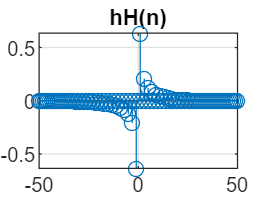

clear all; close all;

% Weights h(n) and frequency response H(f) of Hilbert filter (-pi/2 rad phase shifter)

fs = 2000;                                  % sampling frequency
M=50; N=2*M+1; n=-M:M;                      % filter length, indexes of samples
h = (1-cos(pi*n)) ./ (pi*n); h(M+1) = 0;    % filter weights = impulse response
h = h .* kaiser(N,10)';                     % windowing
stem(n,h); title('hH(n)'); grid;            % plot of the Hilbert filter weights 

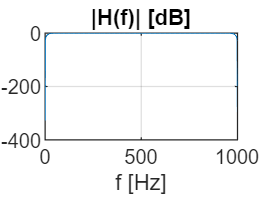

f = 0 : 1 : fs/2;                           % frequencies of interest
z = exp(-j*2*pi*f/fs);                      % variable z^(-1) of the Z transform
H = polyval(h(N:-1:1),z);                   % value of H(z) polynomial
H = H .* exp(j*2*pi*f/fs*M);                % correction of time shift by M samples
figure; plot( f, 20*log10( abs(H))); xlabel('f [Hz]'); title('|H(f)| [dB]'); grid;

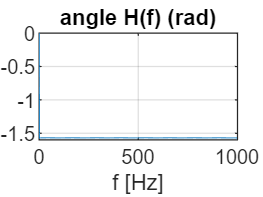

figure; plot( f, unwrap(angle(H)));  xlabel('f [Hz]'); title('angle H(f) (rad)'); grid;

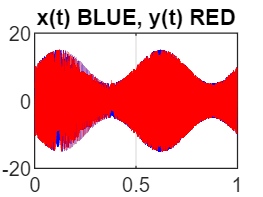


% Example of AM-AM demodulation

Nx=2000; n=0:Nx-1; dt=1/fs; t=dt*n;                              % number of signal samples
A=10; kA=0.5; fA=2; xA = A*(1 + kA*sin(2*pi*fA*t));              % AM
kF=250; fF=1;       xF = kF*sin(2*pi*fF*t);                      % FM
fc=500;             x = xA .* sin(2*pi*(fc*t + cumsum(xF)*dt));  % modulated carrier

% Analytic signal calculation

if(1)           % in frequency domain
   X = fft(x);                      % signal FFT, then its modification: 
   X(1)=0; X(Nx/2+1)=0;             % # 0 for 0 Hz and fs/2
   X(2:Nx/2)    = -j*X(2:Nx/2);     % # (-j) for positive frequencies
   X(Nx/2+2:Nx) =  j*X(Nx/2+2:Nx);  % # (+j) for negative frequencies
   y = ifft(X);                     % inverse FFT of the modified spectrum
   xa = x + j*y;                    % creation of analytic signal
   xa = hilbert( x );               % the same: analytic signal calculated by Matlab
   nn = 1 : Nx;                     % new n
else                 % in time domain
   y = filter(h,1,x);               % Hilbert filtering, i.e. convolution of x(n) with hH(n)
   y = y(2*M+1 : Nx  );             %
   x = x(M+1   : Nx-M);             % removing transient states and synchronization
   t = t(M+1   : Nx-M);             %
   xa = x + j*y;                    % analytic signal
   nn = M+1 : Nx-M;                 % new n
end

xAest = abs( xa );                                          % AM (amplitude) demodulation
ang = unwrap( angle( xa ) );                                % PM (phase)     demodulation
xFest = (1/(2*pi)) * (ang(3:end)-ang(1:end-2)) / (2*dt);    % FM (frequency) demodulation

figure; plot(t,x,'b',t,y,'r'); grid; title('x(t) BLUE, y(t) RED');

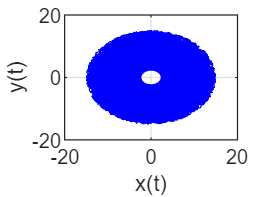

figure; plot(x,y,'b'); grid; xlabel('x(t)'); ylabel('y(t)');

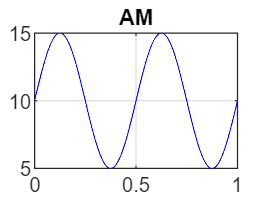

figure; plot(t,xA(nn),'r-',t,xAest,'b-'); title('AM'); grid;

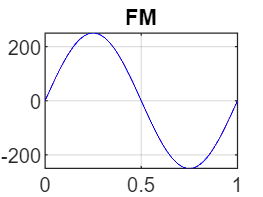

figure; plot(t,xF(nn),'r-',t(2:end-1),xFest-fc,'b-'); title('FM'); grid;

## FIR differentiation filter

Continuous Fourier transform has the following feature:

$F \left( \frac{d x(t)}{dt}\right) = j 2\pi f\cdot X(f)$,

namely, CFT of the signal derivative is equal to CFT of the original signal $X(f)$ multiplied by $j \omega$. We can conclude from this, that frequency response of an analog differentiation filter is equal:


$$H_D(f)=j 2\pi f$$


When we calculate inverse DtFT of $H_D(f)$, we obtain theoretical impulse response (weights) of the digital FIR differentiation filter:

$h_D(n)=\frac{\cos(\pi n)}{n}, \;\; h(0)=0$.

In order to remove oscillations from the filter frequency response, i.e. DtFT of $h_{D}(n)$, the weights $h_{D}(n)$ should be *softly* shaped/tapered on both edges, i.e. multiplied by a appropriately chosen window function:


$$h_D^{(w)} = h_D(n) \cdot w(n), \qquad n=-P,...,-1,0,1,...,P.$$


The simplest differentiation filter weights used in numerical analysis are as follows:

$h_{D2}=\frac{1}{dt}[-1,1], \qquad h_{D3}=\frac{1}{2 \cdot dt}[-1,0,1], \qquad h_{D5}=\frac{1}{12 \cdot dt}[1,-8,0,8,-1]$.

**Analyze the Matlab code. **Run it, observe figures, explain them to your boyfriend/girlfriend. Change: filter length, window used, processed signal (for example to a single cosine with very low, medium and very high frequency).

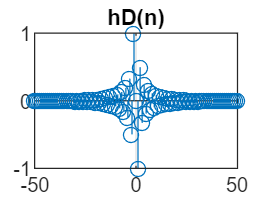

clear all;

% Differentiation filter weights
M=50; N=2*M+1; n=-M:M; h=cos(pi*n)./n; h(M+1)=0;
h = h .* kaiser(N,10)';
%h = 1/12 * [-1, 8, 0, -8, 1]; M=2; N=2*M+1; n = -M:M; % 1/2*[-1 0 1]
stem(n,h); title('hD(n)'); grid;

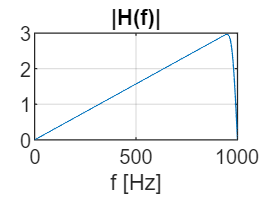


% Verification of filter responses: amplitude, phase, impulse, step
fs = 2000; f = 0:1:fs/2;          % sampling frequency [Hz], frequencies of interest 
z = exp(-j*2*pi*f/fs);            % Z transform variable z^(-1)
H = polyval(h(end:-1:1),z);       % value of H(z) polynomial
% H = freqz(h,1,f,fs);            % all-in-one Matlab function
figure; plot(f,abs(H)); xlabel('f [Hz]'); title('|H(f)|'); grid;

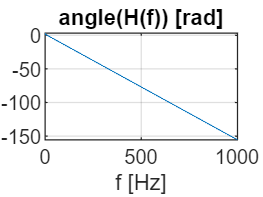

figure; plot(f,unwrap(angle(H))); xlabel('f [Hz]'); title('angle(H(f)) [rad]'); grid;

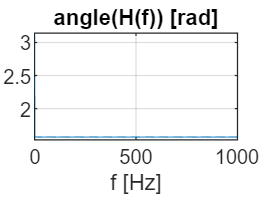

figure; plot(f,angle(exp(j*2*pi*f/fs*M).*H)); xlabel('f [Hz]'); title('angle(H(f)) [rad]'); grid;

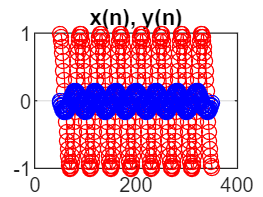


% Filtering - signal differentiation
Nx=400; n=0:Nx-1; dt=1/fs; t=dt*n;
fx=50; x=sin(2*pi*fx*t);
y=filter(h,1,x);
nx=M+1:Nx-M; ny=2*M+1:Nx;
figure; plot(nx,x(nx),'ro-',nx,y(ny),'bo-'); title('x(n), y(n)'); grid; 